### POSTURE VALIDATION

## Initialization

clear 
close all
clc


set_param('full_system', "FastRestart", "off");


## Parameters Setting

% Model Parameters

% Posture regulation strategy filename            
% Available options for easy testing:
% posture = 'posture_subsys'; 
posture = 'cartesian_subsys';

% Trajectory tracking strategy filename
% Available options for easy testing:
% trajectory = 'feed_lin_sagittal_sub';
% trajectory = 'feed_lin_double_deriv_sub';
% trajectory = 'trajectory_tracking_linear_sub';
 trajectory = 'trajectory_tracking_non_linear_sub'; 


distance_threshold = 0.001;                 % Distance threshold for control strategy switch

% Controller Gains

sagittal_K = [10; 56];                   % Sagittal Axis Controller Gain

double_deriv_Kp = [2 0; 0 5];           % Double Derivative Controller Gains
double_deriv_Kd = [5 0; 0 5];

csi = 1/sqrt(2);                        % (Non)Linear Trajectory Tracking Dampening Factor
a = 5;                                  % " Gain

b = 2;                                  % " Gain


% Test Parameters

N = 150;                                % Number of test runs for validation


% !!! need clarification !!!
delta = 0.01*pi;
results = zeros(N,10);

## Model Control Strategy Setting

% vvv DON'T CHANGE THIS CODE IF YOU DON'T KNOW WHAT YOU ARE DOING !!! vvv

set_param('full_system', "FastRestart", "off");

% Change the posture regulation strategy
set_param('full_system/Agent 1/PR', 'ReferencedSubsystem', posture);

% Change the trajectory tracking strategy
set_param('full_system/Agent 1/TT', 'ReferencedSubsystem', trajectory);

% Save model
 save_system('full_system', 'SaveDirtyReferencedModels', 'on')

% ^^^ --------------------------------------------------------------- ^^^

% initial_conditions_1 = [-8 -8 pi/2];
% initial_conditions_2 = [8 8 3*pi/2];
% initial_conditions_3 = [4 -9 1.2*pi];
% 
% initial_conditions_1 = [-8 8 pi/2];
% initial_conditions_2 = [7 7 0];
% initial_conditions_3 = [5 -7 pi/2];
% 
% initial_conditions_1 = [7 9 pi];
% initial_conditions_2 = [-9 3 0.3*pi];
% initial_conditions_3 = [-4 9 1.3*pi];
% 
% initial_conditions_1 = [10 -2 1.4*pi];
% initial_conditions_2 = [-3 6 0.8*pi];
% initial_conditions_3 = [-6 -6 1.4*pi];

initial_conditions_1 = [-8 4 pi/2];
initial_conditions_2 = [-8 -4 3*pi/2];
initial_conditions_3 = [8 0 1.2*pi];


## Model Validation Through Random Initial Condition Generation

w = warning('off','all');

initial_conditions_trans_1 = state_transformation([0,0,0], initial_conditions_1);
initial_conditions_trans_2 = state_transformation([0,0,0], initial_conditions_2);
initial_conditions_trans_3 = state_transformation([0,0,0], initial_conditions_3);

out = sim('full_system', "StopTime", "10");
warning(w);

VISUALIZATION

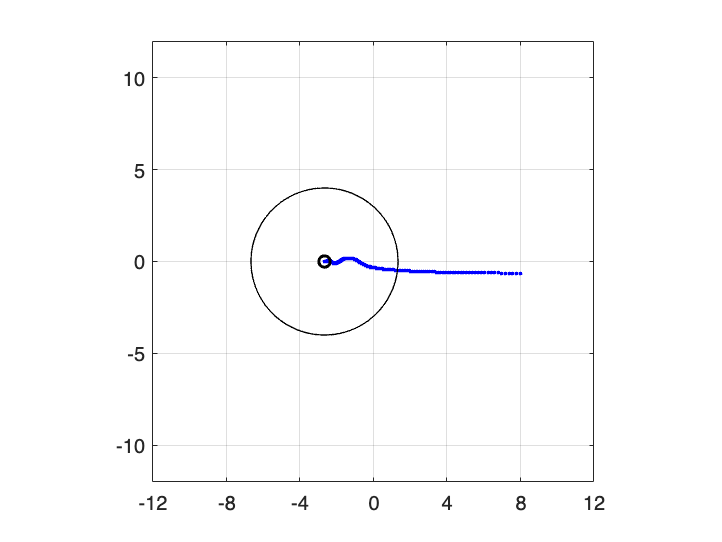

consensus = out.consensus.signals.values;
time = out.tout.';
enables1 = out.enables.signals(1).values;
enables1 = ~enables1;
l1 = find(enables1, 1, 'first');
en1 = time(l1);

enables2 = out.enables.signals(2).values;
enables2 = ~enables2;
l2 = find(enables2, 1, 'first');
en2 = time(l2);

enables3 = out.enables.signals(3).values;
enables3 = ~enables3;
l3 = find(enables3, 1, 'first');
en3 = time(l3);

xpos1 = out.data.signals(1).values(1:l1,3);
xpos1 = reshape(xpos1, [1, size(xpos1, 1)]);
ypos1 = out.data.signals(1).values(1:l1,4);
ypos1 = reshape(ypos1, [1, size(ypos1, 1)]);
th1 = out.data.signals(1).values(1:l1,5);
th1 = reshape(th1, [1, size(th1, 1)]);

xpos2 = out.data.signals(2).values(1:l2,3);
xpos2 = reshape(xpos2, [1, size(xpos2, 1)]);
ypos2 = out.data.signals(2).values(1:l2,4);
ypos2 = reshape(ypos2, [1, size(ypos2, 1)]);
th2 = out.data.signals(2).values(1:l2,5);
th2 = reshape(th2, [1, size(th2, 1)]);

xpos3 = out.data.signals(3).values(1:l3,3);
xpos3 = reshape(xpos3, [1, size(xpos3, 1)]);
ypos3 = out.data.signals(3).values(1:l3,4);
ypos3 = reshape(ypos3, [1, size(ypos3, 1)]);
th3 = out.data.signals(3).values(1:l3,5);
th3 = reshape(th3, [1, size(th3, 1)]);

xref = out.data.signals(1).values(:,1);
xref = reshape(xref, [1, size(xref, 1)]);
yref = out.data.signals(1).values(:,2);
yref = reshape(yref, [1, size(yref, 1)]);



n = numel(xpos1);
min_window = -12;
max_window = 12;
tick_step = 4;
bound = 2;


figure
axis equal
box on;
grid on;
xlim([min_window max_window])
ylim([min_window max_window])

xticks(min_window:4:max_window)
hold on

scatter(xpos1,ypos1, 32, '.r');
scatter(xpos2,ypos2, 32, '.g');
scatter(xpos3,ypos3, 32, '.b');
scatter(consensus(1),consensus(2), 32, 'ok', 'LineWidth',1.5);
circle(consensus(1),consensus(2),4);

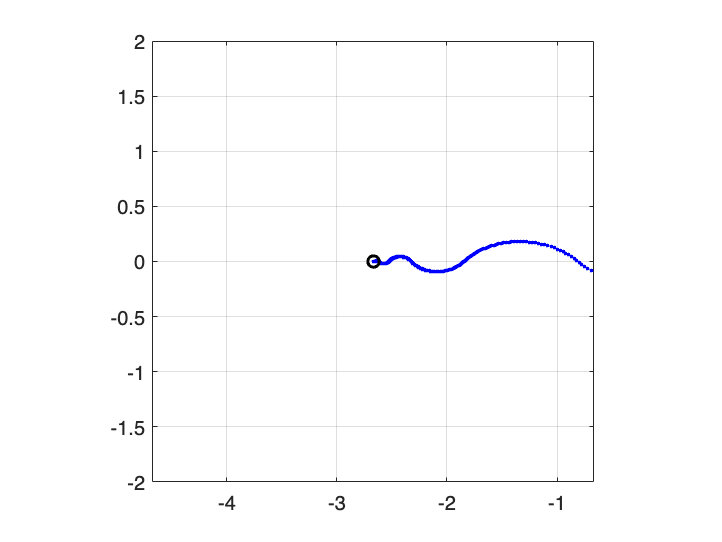


figure
axis equal
box on
hold on
grid on


xlim([consensus(1)-bound consensus(1)+bound])
ylim([consensus(2)-bound consensus(2)+bound])

scatter(xpos1,ypos1, 32, '.r');
scatter(xpos2,ypos2, 32, '.g');
scatter(xpos3,ypos3, 32, '.b');
scatter(consensus(1),consensus(2), 32, 'ok', 'LineWidth',1.5);


figure
box on;
grid on;
hold on;
legend on;

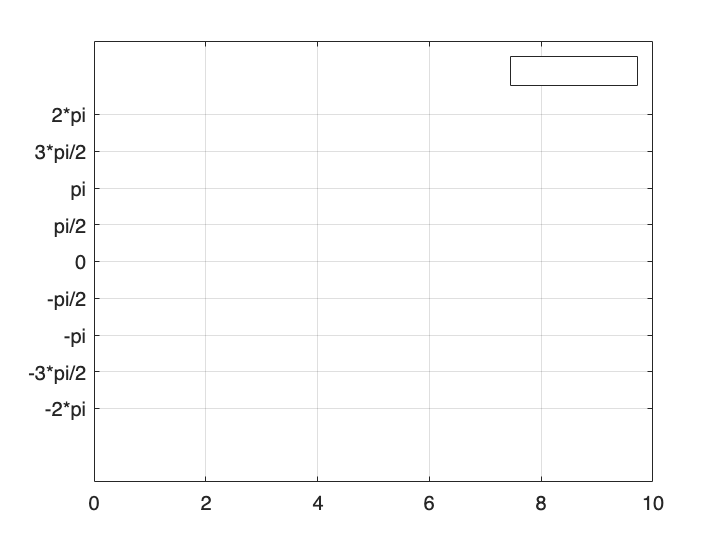


xlim([0 10])
ylim([-3*pi 3*pi])
set(gca,'YTick',-2*pi:pi/2:2*pi) 
set(gca,'YTickLabel',{'-2*pi','-3*pi/2','-pi','-pi/2','0','pi/2','pi','3*pi/2','2*pi'})


plot(time(1:l1), th1,'DisplayName','agent 1 orientation', LineWidth=1.5, Color='r');
xline(en1, 'DisplayName','ctrl switch', LineWidth=1, LineStyle="-.");

Error using xline
Value must be scalar.


figure
box on;
grid on;
hold on;
legend on;

xlim([0 10])
ylim([-3*pi 3*pi])
set(gca,'YTick',-2*pi:pi/2:2*pi) 
set(gca,'YTickLabel',{'-2*pi','-3*pi/2','-pi','-pi/2','0','pi/2','pi','3*pi/2','2*pi'})

plot(time(1:l2), th2,'DisplayName','agent 2 orientation', LineWidth=1.5, Color='g');
xline(en2, 'DisplayName','ctrl switch', LineWidth=1, LineStyle="-.");

figure
box on;
grid on;
hold on;
legend on;

xlim([0 10])
ylim([-3*pi 3*pi])
set(gca,'YTick',-2*pi:pi/2:2*pi) 
set(gca,'YTickLabel',{'-2*pi','-3*pi/2','-pi','-pi/2','0','pi/2','pi','3*pi/2','2*pi'})

plot(time(1:l3), th3,'DisplayName','agent 3 orientation', LineWidth=1.5, Color='b');
xline(en3, 'DisplayName','ctrl switch', LineWidth=1, LineStyle="-.");

function circle(x,y,r)
%x and y are the coordinates of the center of the circle
%r is the radius of the circle
%0.01 is the angle step, bigger values will draw the circle faster but
%you might notice imperfections (not very smooth)
ang=0:0.01:2*pi; 
xp=r*cos(ang);
yp=r*sin(ang);
plot(x+xp,y+yp, LineWidth=0.7, Color='k');
end